% This simulation simulates the ability to detect intensity change of one
% sensor when another sensor shows a large dynamic change during multiplex
% fluorescence lifetime and intensity imaging.

% Create the directory to save the data for the simulation

SimulationName='Simulation_Multiplexing_FigureS8_50ns_20240617';

savefolder='/Volumes/ChenLabHDDB/Simulation/';
% create the simulation folder
cd(savefolder)
mkdir(SimulationName)

% go to the simulation folder
filepath=[savefolder SimulationName '/']

filepath = '/Volumes/ChenLabHDDB/Simulation/Simulation_Multiplexing_FigureS8_50ns_20240617/'

cd(filepath)


% Define the double exponential decay parameters, photon numbers, and afterpulse ratio in
% the simulation

% Photon number series for sensor A and sensor B
SS_samples_A = 200000:5000:900000;
SS_samples_B = 200000:5000:900000;

% Define a dynamic range of 2 fold change for the other sensor when
% evaluating one certain sensor
SS_samples_ConstantOne = (200000:50000:600000)*2;

tau1=2; % tau1 
tau2=4; % tau2 

afterpulse_ratio=0.0032; % Afterpulse ratio experimentally determined as 0.32% of the fluorescence signal

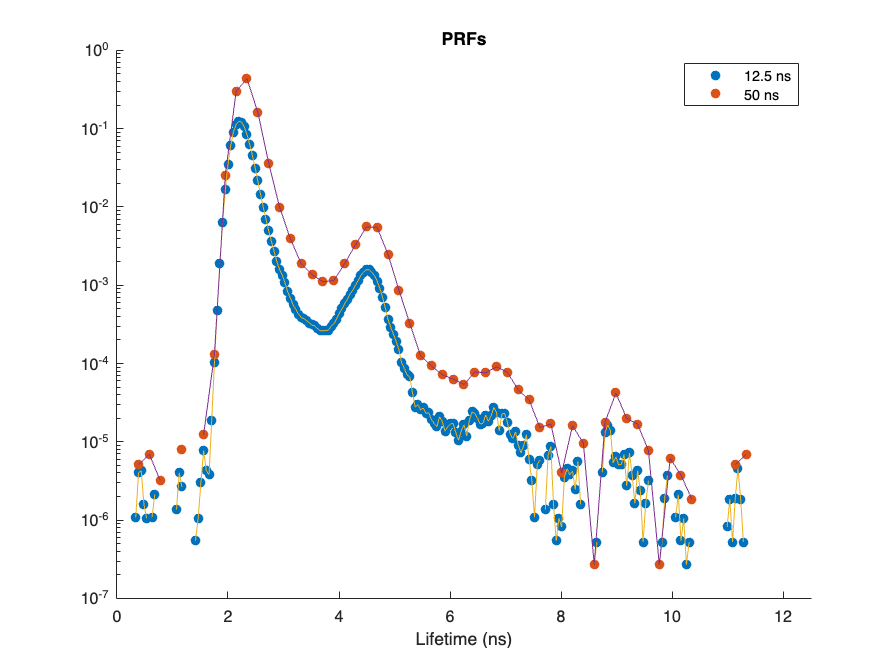

% load the atuofluorescence fitting results and the delta peak time to
% adjust the prf
load("AKAR_baseline_fitting_parameters.mat")
load('Autofluo_fitting_parameters')

% Adjust IRF by dpt
PrfName_original = 'prf_InsightBottomGreen_20231017.mat'; % This is the original collected IRF file
load(PrfName_original) % Load the original prf file
x = (1:1:256)*(12.5/256); % Spreading the x axis (256 time channels) over 12.5ns
prf_interp1=interp1(x,prf,x+dpt,'linear'); % Adjust the prf based on delta peak time
prf_interp1(isnan(prf_interp1)) = 0; % Make the nan values to 0 after interpolation
prf_original = prf_interp1; % IRF variable has to be saved under the name prf


% PRF was collected as 256-channel vector spanning a laser cycle of 12.5
% ns; when changing to 50 ns, PRF will be modified to keep the same FWHM
x_axis = 1:1:256;
prf_50ns = zeros(1,256);

for i = 1:64
    prf_50ns(i) = sum(prf_original((i-1)*4+1:(i-1)*4+4));

end

% Plot the PRF for 12.5 ns and 50 ns
figure
scatter(x_axis*(12.5/256), prf_original, 'filled')
hold on
scatter(x_axis*(50/256), prf_50ns, 'filled')
hold on
plot(x_axis*(12.5/256), prf_original)
hold on
plot(x_axis*(50/256), prf_50ns)
xlim([0 12.5])
xlabel('Lifetime (ns)')
set(gca,'yscale', 'log')
legend('12.5 ns', '50 ns')
title('PRFs')


prf = prf_50ns;

% save the new prf as new file
PrfName = 'Prf_interp1_50ns.mat' 

PrfName = 'Prf_interp1_50ns.mat'

save(PrfName, 'prf')

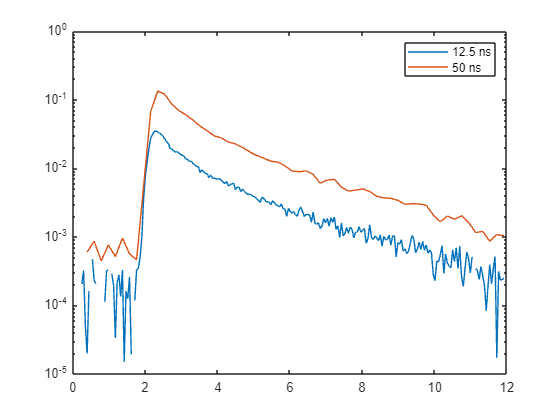

% Create the probability distribution function of autofluorescence
% corresponding to a 50 ns cycle; make the autoflurescence photon number as
% 3.2 fold of the original one for 12.5 ns

autofluo_corrected(246:end) = 0;
autofluo_corrected = autofluo_corrected/sum(autofluo_corrected);

x_axis = 1:1:256;
autofluo_50ns = zeros(1,256);

for i = 1:64
    autofluo_50ns(i) = sum(autofluo_corrected((i-1)*4+1:(i-1)*4+4));

end

figure
semilogy(x_axis*(12.5/256), autofluo_corrected)
hold on
semilogy(x_axis*(50/256), autofluo_50ns)
legend('12.5 ns', '50 ns')


autofluo_number = AF_mean_corrected*3.2;


% This is to create the distribution of background
bkgrd_AP_distribution = zeros(1, 256) + 1/251; % Creating the probability density distribution: background evenly distributed over time; the experimental histogram channel 1-4 and 256 are 0; thus there are 251 channels that add up to 1
bkgrd_AP_distribution([1,2,3,4,256]) = 0; % Probability density distribution for background: channel 1-4 and 256 as 0
bkgrd_sum = round(autofluo_bkgrd*251)*3.2; % background total number: autofluo_bkgrd is background photon number per channel from the fitting of autofluorescence; make the background photon number as
% 3.2 fold of the original one for 12.5 ns

c = parcluster()

c = 

 Local Cluster

    Properties: 

                   Profile: Processes
                  Modified: false
                      Host: ag000wd-400wkq3
                NumWorkers: 4
                NumThreads: 1

        JobStorageLocation: C:\Users\b.waleed\AppData\Roaming\MathWorks\MATLAB\local_cluster_jobs\R2022b
   RequiresOnlineLicensing: false

    

% create the scripts for batch processing
edit Simulation_sampleA.m
edit Simulation_sampleB.m

% batch processing for simulation of sample A with different photon numbers
PopulationName='Simulation_population_A_2ns.mat';

for i = 1:length(SS_samples_A)
    SS = SS_samples_A(i);
    batch('Simulation_sampleA')
end

ans = 

 Job

    Properties: 

                   ID: 301
                 Type: independent
             Username: b.waleed
                State: running
       SubmitDateTime: 17-Jun-2024 16:03:25
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 


for i = 1:length(SS_samples_ConstantOne)
    SS = SS_samples_ConstantOne(i);
    batch('Simulation_sampleA')
end

ans = 

 Job

    Properties: 

                   ID: 442
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 17-Jun-2024 16:10:06
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

% batch processing for simulation of sample B with different photon numbers
PopulationName='Simulation_population_B_4ns.mat';

for i = 1:length(SS_samples_B)
    SS = SS_samples_B(i);
    batch('Simulation_sampleB')
end

ans = 

 Job

    Properties: 

                   ID: 451
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 17-Jun-2024 17:09:47
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 


for i = 1:length(SS_samples_ConstantOne)
    SS = SS_samples_ConstantOne(i);
    batch('Simulation_sampleB')
end

ans = 

 Job

    Properties: 

                   ID: 592
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 17-Jun-2024 17:15:57
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

% create the scripts for batch processing
edit Autofluo_corrected_simulation_20231201.m
edit Bkgrd_AP_simulation_20231201.m

c = parcluster()

c = 

 Local Cluster

    Properties: 

                   Profile: Processes
                  Modified: false
                      Host: ag000wd-400wkq3
                NumWorkers: 4
                NumThreads: 1

        JobStorageLocation: C:\Users\b.waleed\AppData\Roaming\MathWorks\MATLAB\local_cluster_jobs\R2022b
   RequiresOnlineLicensing: false

    

% Batch processing of simulation of corrected autofluorescence and
% background/afterpulse

SS_samples = 200000:5000:600000;

SS_samples_ConstantOne = (200000:100000:600000)*2;

for i=1:length(SS_samples)
    
    for j = 1:length(SS_samples_ConstantOne)

        SS = SS_samples(i) + SS_samples_ConstantOne(j);

        batch('Bkgrd_AP_simulation_20231201')
        batch('Autofluo_corrected_simulation_20231201')

    end
end

ans = 

 Job



ans = 

 Job

    Properties: 

                   ID: 602
                 Type: independent
             Username: b.waleed
                State: running
       SubmitDateTime: 26-Jun-2024 10:02:06
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 603
                 Type: independent
             Username: b.waleed
                State: running
       SubmitDateTime: 26-Jun-2024 10:02:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 604
                 Type: independent
             Username: b.waleed
                State: running
       SubmitDateTime: 26-Jun-2024 10:02:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 605
                 Type: independent
             Username: b.waleed
                State: running
       SubmitDateTime: 26-Jun-2024 10:02:17
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 606
                 Type: independent
             Username: b.waleed
                State: running
       SubmitDateTime: 26-Jun-2024 10:02:20
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 607
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:02:24
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 608
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:02:27
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 609
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:02:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 610
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:02:34
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 611
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:02:37
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 612
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:02:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 613
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:02:44
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 614
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:02:47
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 615
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:02:50
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 616
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:02:53
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 617
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:02:57
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 618
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 619
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:03
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 620
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:07
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 621
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 622
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 623
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:17
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 624
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:20
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 625
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 626
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:27
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 627
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 628
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:33
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 629
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 630
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 631
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:43
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 632
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:46
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 633
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:50
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 634
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:53
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 635
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:03:56
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 636
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 637
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:03
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 638
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:06
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 639
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:09
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 640
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 641
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:16
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 642
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:19
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 643
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 644
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 645
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 646
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:33
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 647
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 648
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 649
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:43
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 650
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:46
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 651
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:50
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 652
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:53
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 653
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:04:56
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 654
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 655
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:03
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 656
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:07
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 657
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 658
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:14
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 659
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:17
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 660
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:21
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 661
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:24
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 662
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:27
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 663
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 664
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:34
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 665
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:37
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 666
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:41
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 667
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:44
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 668
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:48
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 669
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:51
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 670
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:55
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 671
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:05:58
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 672
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:01
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 673
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:05
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 674
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:08
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 675
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:11
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 676
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:15
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 677
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:18
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 678
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:21
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 679
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:25
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 680
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:28
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 681
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:31
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 682
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:35
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 683
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:38
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 684
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:42
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 685
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:45
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 686
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:49
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 687
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:52
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 688
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:55
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 689
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:06:59
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 690
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:02
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 691
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:05
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 692
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:09
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 693
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:12
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 694
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:15
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 695
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:19
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 696
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:22
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 697
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:25
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 698
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 699
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:32
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 700
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:35
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 701
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:39
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 702
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:42
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 703
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:46
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 704
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:49
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 705
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:52
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 706
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:56
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 707
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:07:59
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 708
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:08:02
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 709
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:08:06
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 710
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:08:09
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 711
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:08:12
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 712
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:08:16
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 713
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:08:19
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 714
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:08:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 715
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:08:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 716
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:08:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 717
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:08:33
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 718
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:08:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 719
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:08:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 720
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:08:43
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 721
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:08:46
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 722
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:08:50
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 723
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:08:53
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 724
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:08:56
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 725
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 726
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:03
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 727
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:07
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 728
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 729
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 730
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:17
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 731
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:20
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 732
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 733
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:27
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 734
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 735
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:33
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 736
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:37
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 737
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 738
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:43
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 739
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:47
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 740
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:50
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 741
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:53
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 742
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:09:57
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 743
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 744
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:04
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 745
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:07
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 746
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 747
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:14
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 748
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:17
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 749
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:21
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 750
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:24
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 751
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:28
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 752
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:31
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 753
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:34
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 754
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:38
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 755
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:42
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 756
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:45
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 757
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:48
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 758
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:52
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 759
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:55
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 760
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:10:58
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 761
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:11:02
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 762
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:11:05
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 763
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:11:09
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 764
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:11:12
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 765
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:11:16
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 766
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:11:19
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 767
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:11:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 768
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:11:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 769
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:11:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 770
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:11:33
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 771
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:11:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 772
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:11:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 773
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:11:43
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 774
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:11:46
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 775
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:11:50
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 776
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:11:53
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 777
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:11:57
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 778
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 779
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:03
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 780
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:06
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 781
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 782
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 783
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:16
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 784
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:20
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 785
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 786
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 787
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 788
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:33
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 789
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:37
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 790
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 791
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:44
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 792
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:47
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 793
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:50
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 794
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:53
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 795
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:12:57
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 796
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 797
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:04
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 798
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:07
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 799
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 800
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 801
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:16
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 802
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:19
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 803
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:22
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 804
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:25
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 805
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:28
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 806
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:31
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 807
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:33
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 808
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 809
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:39
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 810
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:42
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 811
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:45
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 812
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:48
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 813
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:51
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 814
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:54
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 815
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:13:57
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 816
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 817
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:02
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 818
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:05
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 819
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:08
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 820
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:11
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 821
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:15
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 822
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:18
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 823
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:21
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 824
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:24
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 825
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:27
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 826
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 827
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:33
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 828
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 829
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:39
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 830
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:41
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 831
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:44
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 832
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:48
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 833
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:51
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 834
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:54
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 835
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:14:57
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 836
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 837
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:03
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 838
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:06
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 839
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:08
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 840
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:11
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 841
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:14
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 842
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:17
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 843
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:20
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 844
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 845
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 846
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 847
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:31
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 848
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:34
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 849
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:37
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 850
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 851
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:43
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 852
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:46
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 853
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:49
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 854
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:52
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 855
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:55
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 856
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:15:58
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 857
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:01
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 858
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:04
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 859
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:07
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 860
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 861
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:12
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 862
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:15
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 863
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:18
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 864
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:21
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 865
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:24
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 866
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:27
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 867
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 868
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:33
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 869
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:37
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 870
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 871
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:43
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 872
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:46
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 873
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:48
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 874
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:51
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 875
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:54
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 876
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:16:57
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 877
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 878
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:03
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 879
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:06
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 880
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:09
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 881
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:12
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 882
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:15
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 883
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:18
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 884
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:21
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 885
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:24
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 886
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:27
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 887
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 888
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:33
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 889
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 890
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:39
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 891
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:42
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 892
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:45
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 893
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:48
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 894
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:51
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 895
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:54
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 896
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:56
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 897
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:17:59
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 898
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:02
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 899
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:05
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 900
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:08
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 901
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:11
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 902
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:14
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 903
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:17
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 904
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:20
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 905
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 906
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 907
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 908
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:32
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 909
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:35
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 910
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:38
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 911
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:41
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 912
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:43
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 913
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:46
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 914
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:49
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 915
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:52
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 916
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:55
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 917
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:18:58
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 918
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:01
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 919
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:04
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 920
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:07
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 921
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 922
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 923
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:16
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 924
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:18
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 925
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:21
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 926
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:24
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 927
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:27
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 928
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 929
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:33
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 930
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 931
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:38
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 932
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:41
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 933
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:44
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 934
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:47
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 935
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:50
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 936
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:53
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 937
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:56
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 938
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:19:59
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 939
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:02
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 940
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:05
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 941
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:08
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 942
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 943
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 944
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:16
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 945
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:19
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 946
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:22
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 947
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:25
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 948
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:28
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 949
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:31
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 950
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:34
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 951
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 952
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:39
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 953
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:42
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 954
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:45
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 955
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:48
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 956
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:51
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 957
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:54
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 958
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:20:57
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 959
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 960
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:02
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 961
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:05
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 962
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:08
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 963
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:11
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 964
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:14
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 965
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:17
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 966
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:20
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 967
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 968
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 969
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 970
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:31
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 971
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:34
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 972
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:37
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 973
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 974
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:43
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 975
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:46
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 976
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:49
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 977
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:52
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 978
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:55
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 979
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:21:58
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 980
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 981
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:03
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 982
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:06
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 983
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:09
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 984
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:12
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 985
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:15
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 986
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:18
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 987
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:21
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 988
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:24
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 989
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 990
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 991
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:32
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 992
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:35
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 993
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:38
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 994
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:41
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 995
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:44
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 996
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:47
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 997
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:50
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 998
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:53
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 999
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:56
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1000
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:22:59
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1001
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:02
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1002
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:05
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1003
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:07
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1004
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1005
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1006
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:16
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1007
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:19
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1008
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:22
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1009
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:25
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1010
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:28
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1011
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:31
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1012
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:34
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1013
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1014
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:39
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1015
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:42
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1016
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:45
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1017
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:48
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1018
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:51
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1019
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:54
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1020
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:57
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1021
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:23:59
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1022
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:02
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1023
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:05
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1024
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:08
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1025
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:11
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1026
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:14
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1027
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:17
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1028
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:20
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1029
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1030
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1031
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1032
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:32
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1033
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:34
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1034
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:37
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1035
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:41
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1036
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:44
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1037
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:46
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1038
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:49
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1039
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:52
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1040
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:55
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1041
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:24:58
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1042
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:01
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1043
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:04
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1044
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:07
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1045
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1046
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1047
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:15
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1048
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:18
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1049
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:21
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1050
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:24
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1051
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:27
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1052
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1053
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:33
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1054
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1055
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:38
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1056
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:41
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1057
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:44
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1058
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:47
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1059
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:50
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1060
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:53
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1061
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:56
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1062
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:25:59
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1063
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:02
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1064
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:04
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1065
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:07
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1066
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1067
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1068
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:16
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1069
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:19
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1070
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:22
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1071
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:25
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1072
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:28
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1073
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:31
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1074
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:34
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1075
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:37
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1076
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1077
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:42
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1078
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:45
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1079
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:48
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1080
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:51
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1081
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:54
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1082
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:26:57
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1083
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1084
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:03
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1085
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:05
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1086
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:08
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1087
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:11
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1088
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:14
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1089
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:17
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1090
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:20
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1091
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1092
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1093
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1094
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:32
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1095
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:35
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1096
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:38
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1097
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1098
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:43
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1099
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:46
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1100
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:49
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1101
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:52
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1102
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:55
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1103
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:27:58
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1104
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:01
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1105
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:04
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1106
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:07
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1107
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1108
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1109
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:16
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1110
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:19
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1111
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:21
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1112
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:24
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1113
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:27
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1114
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1115
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:33
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1116
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1117
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:39
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1118
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:42
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1119
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:45
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1120
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:48
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1121
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:50
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1122
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:53
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1123
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:56
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1124
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:28:59
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1125
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:02
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1126
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:05
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1127
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:08
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1128
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1129
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1130
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:16
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1131
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:19
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1132
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:22
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1133
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:25
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1134
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:28
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1135
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:31
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1136
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:34
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1137
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1138
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:39
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1139
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:42
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1140
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:45
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1141
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:48
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1142
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:51
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1143
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:54
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1144
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:29:57
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1145
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1146
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:03
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1147
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:05
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1148
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:08
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1149
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:11
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1150
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:14
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1151
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:17
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1152
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:20
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1153
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1154
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1155
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1156
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:32
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1157
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:35
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1158
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:37
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1159
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1160
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:43
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1161
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:46
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1162
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:49
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1163
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:52
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1164
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:55
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1165
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:30:58
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1166
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:01
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1167
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:04
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1168
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:06
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1169
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:09
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1170
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:12
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1171
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:15
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1172
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:18
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1173
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:21
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1174
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:24
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1175
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:27
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1176
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1177
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:32
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1178
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:35
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1179
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:38
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1180
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:41
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1181
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:44
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1182
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:47
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1183
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:50
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1184
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:53
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1185
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:56
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1186
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:31:59
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1187
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:02
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1188
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:04
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1189
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:07
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1190
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1191
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1192
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:16
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1193
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:19
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1194
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:22
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1195
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:25
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1196
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:28
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1197
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:31
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1198
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:34
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1199
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1200
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:39
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1201
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:42
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1202
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:45
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1203
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:48
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1204
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:51
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1205
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:54
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1206
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:32:57
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1207
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1208
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:03
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1209
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:06
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1210
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:09
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1211
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:12
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1212
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:14
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1213
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:17
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1214
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:20
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1215
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1216
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1217
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1218
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:32
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1219
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:35
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1220
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:37
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1221
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1222
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:43
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1223
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:46
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1224
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:49
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1225
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:52
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1226
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:55
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1227
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:33:58
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1228
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:01
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1229
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:03
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1230
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:06
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1231
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:09
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1232
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:12
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1233
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:15
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1234
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:18
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1235
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:21
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1236
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:24
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1237
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1238
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1239
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:32
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1240
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:35
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1241
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:39
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1242
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:43
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1243
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:46
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1244
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:49
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1245
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:52
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1246
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:55
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1247
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:34:58
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1248
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:01
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1249
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:04
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1250
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:07
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1251
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1252
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1253
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:16
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1254
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:19
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1255
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:21
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1256
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:24
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1257
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:27
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1258
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1259
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:33
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1260
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1261
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:39
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1262
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:42
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1263
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:45
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1264
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:48
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1265
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:51
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1266
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:54
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1267
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:35:57
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1268
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1269
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:03
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1270
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:05
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1271
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:08
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1272
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:11
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1273
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:14
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1274
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:17
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1275
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:20
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1276
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1277
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1278
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1279
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:31
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1280
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:34
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1281
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:37
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1282
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1283
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:43
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1284
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:46
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1285
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:49
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1286
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:52
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1287
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:55
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1288
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:36:58
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1289
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1290
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:03
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1291
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:06
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1292
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:09
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1293
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:12
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1294
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:15
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1295
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:18
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1296
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:21
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1297
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1298
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1299
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1300
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:32
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1301
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:35
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1302
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:38
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1303
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:41
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1304
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:44
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1305
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:47
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1306
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:50
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1307
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:52
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1308
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:55
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1309
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:37:58
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1310
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:01
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1311
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:04
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1312
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:07
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1313
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1314
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1315
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:16
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1316
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:19
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1317
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:21
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1318
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:25
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1319
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:27
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1320
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1321
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:33
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1322
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1323
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:39
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1324
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:42
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1325
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:45
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1326
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:48
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1327
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:51
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1328
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:54
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1329
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:38:57
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1330
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1331
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:02
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1332
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:05
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1333
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:08
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1334
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:11
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1335
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:14
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1336
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:17
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1337
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:20
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1338
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1339
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1340
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1341
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:32
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1342
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:35
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1343
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:38
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1344
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:41
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1345
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:43
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1346
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:46
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1347
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:49
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1348
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:52
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1349
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:55
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1350
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:39:58
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1351
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:01
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1352
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:04
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1353
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:07
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1354
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:10
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1355
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:12
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1356
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:15
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1357
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:18
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1358
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:21
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1359
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:24
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1360
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:27
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1361
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1362
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:33
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1363
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1364
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:39
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1365
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:42
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1366
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:45
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1367
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:48
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1368
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:50
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1369
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:53
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1370
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:56
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1371
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:40:59
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1372
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:02
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1373
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:05
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1374
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:08
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1375
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:11
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1376
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:14
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1377
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:17
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1378
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:20
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1379
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1380
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1381
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1382
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:32
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1383
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:35
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1384
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:38
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1385
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:41
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1386
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:44
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1387
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:47
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1388
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:50
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1389
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:53
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1390
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:56
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1391
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:41:59
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1392
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:02
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1393
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:05
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1394
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:08
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1395
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:11
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1396
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1397
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:17
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1398
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:20
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1399
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:23
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1400
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1401
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1402
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:32
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1403
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:35
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1404
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:38
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1405
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1406
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:44
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1407
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:47
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1408
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:51
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1409
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:53
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 1410
                 Type: independent
             Username: b.waleed
                State: queued
       SubmitDateTime: 26-Jun-2024 10:42:56
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

## Running fitting

% Define fitting parameters
global FixBackground FixedBackground

FixBackground = 0;

ch = 1; % only for FLIM channel 1
load('Prf_interp1_50ns.mat')
spc.fits{1}.prf = prf;
spc.datainfo.psPerUnit = (50/256)*1000;
spc.datainfo.pulseInt = 50;
spc.fits{1}.fitstart = spc.datainfo.psPerUnit/1000;
spc.fits{1}.fitend = 50;

spc.fits{1}.beta2 = tau1; % p1 and p2 as 0.5
spc.fits{1}.beta4 = tau2;

sample_num = 500;


% look at A changes
SS_samples_A = 200000:100000:600000;
SS_samples_B = 200000:100000:600000;

SS_samples_ConstantOne = (200000:100000:600000)*2;

for i = 5:6

    SS_A_start = [];
    SS_A_start = SS_samples_A(i);

    SS_B = [];
    SS_B = SS_samples_ConstantOne(i);

    fitting_parameters = {};

    p1_fitted = {};

    for j = 1:(((SS_A_start/4)/5000)+1)

        n_all = {};

        SS_A = [];
        SS_A = SS_A_start + (j-1)*5000;

        n_sensor_all_A = [];
        SensorAData = ['simulated_data/SampleA_', num2str(SS_A), '_sensor.mat'];
        load(SensorAData)
        n_sensor_all_A = n_sensor_all;

        n_sensor_all_B = [];
        SensorBData = ['simulated_data/SampleB_4_', num2str(SS_B), '_sensor.mat'];
        load(SensorBData)
        n_sensor_all_B = n_sensor_all;

        AutoFData = ['simulated_data/autoF_', num2str(SS_A+SS_B), '.mat'];
        load(AutoFData)

        BgFData = ['simulated_data/bkgrd_AP_', num2str(SS_A+SS_B), '.mat'];
        load(BgFData)

        n_all{1} = n_sensor_all_A  + n_sensor_all_B + n_auto_all + n_bkgrd_all;

        [p1_fitted_single, tau_empTrunc, fitting_parameters_single] = RunFitting(500, n_all);
        fitting_parameters{j} = fitting_parameters_single;
        p1_fitted{j} = p1_fitted_single;

    end
% 

    savename = ['A_FittingResults_SS_start_', num2str(i), '_',  num2str(SS_A_start), '_20240626.mat'];
    save(savename, 'fitting_parameters', 'p1_fitted')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Look at B changes
    SS_B_start = [];
    SS_B_start = SS_samples_B(i);

    SS_A = [];
    SS_A = SS_samples_ConstantOne(i);

    fitting_parameters = {};

    p1_fitted = {};

    for j = 1:(((SS_B_start/4)/5000)+1)

        n_all = {};

        SS_B = [];
        SS_B = SS_B_start + (j-1)*5000;

        n_sensor_all_A = [];
        SensorAData = ['simulated_data/SampleA_', num2str(SS_A), '_sensor.mat'];
        load(SensorAData)
        n_sensor_all_A = n_sensor_all;

        n_sensor_all_B = [];
        SensorBData = ['simulated_data/SampleB_4_', num2str(SS_B), '_sensor.mat'];
        load(SensorBData)
        n_sensor_all_B = n_sensor_all;

        AutoFData = ['simulated_data/autoF_', num2str(SS_A+SS_B), '.mat'];
        load(AutoFData)

        BgFData = ['simulated_data/bkgrd_AP_', num2str(SS_A+SS_B), '.mat'];
        load(BgFData)

        n_all{1} = n_sensor_all_A  + n_sensor_all_B + n_auto_all + n_bkgrd_all;

        [p1_fitted_single, tau_empTrunc, fitting_parameters_single] = RunFitting(500, n_all);
        fitting_parameters{j} = fitting_parameters_single;
        p1_fitted{j} = p1_fitted_single;

    end


    savename = ['B_FittingResults_SS_start_', num2str(i), '_',  num2str(SS_B_start), '_20240503.mat'];
    save(savename, 'fitting_parameters', 'p1_fitted')

end

Error using load
'simulated_data/autoF_1805000.mat' is not found in the current
folder or on the MATLAB path, but exists in:
    /Volumes/ChenLabHDDB/Simulation/Simulation_Multiplexing_50ns_20240503

    /Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/Simulation_Multiplexing/Simulation_Multiplexing_50ns_20240503

    /Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/Simulation_Multiplexing/Simulation_Multiplexing_MultipleBLifetime_20240123

    /Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/Simulation_Multiplexing/Simulation_Multiplexing_MultipleBLifetime_20240422

Change the MATLAB current folder or add its folder to the MATLAB
path.

% Calculating the minimal detectable difference of sensor A change
SS_samples_A = 200000:100000:600000;
SS_samples_B = 200000:100000:600000;
xsim = (0:1:511)*(50/256);
SaveName = {};
SaveName{1} = 'A_FittingResults_SS_start_';
SaveName{2} = '_20240626';
Beta_target = 'A';
tau1 = 2;
tau2 = 4;
[beta_all_A, A_intensity_all, A_intensity_raw_all, B_intensity_all, B_intensity_raw_all] = CalcIntensity_and_Beta(xsim, prf, SS_samples_A, SaveName, tau1, tau2, Beta_target);

intensity_change_step = 5000;
Max_intensity_fold_change = 0.25;
FigureTitle = '200% B change|A'

FigureTitle = '200% B change|A'

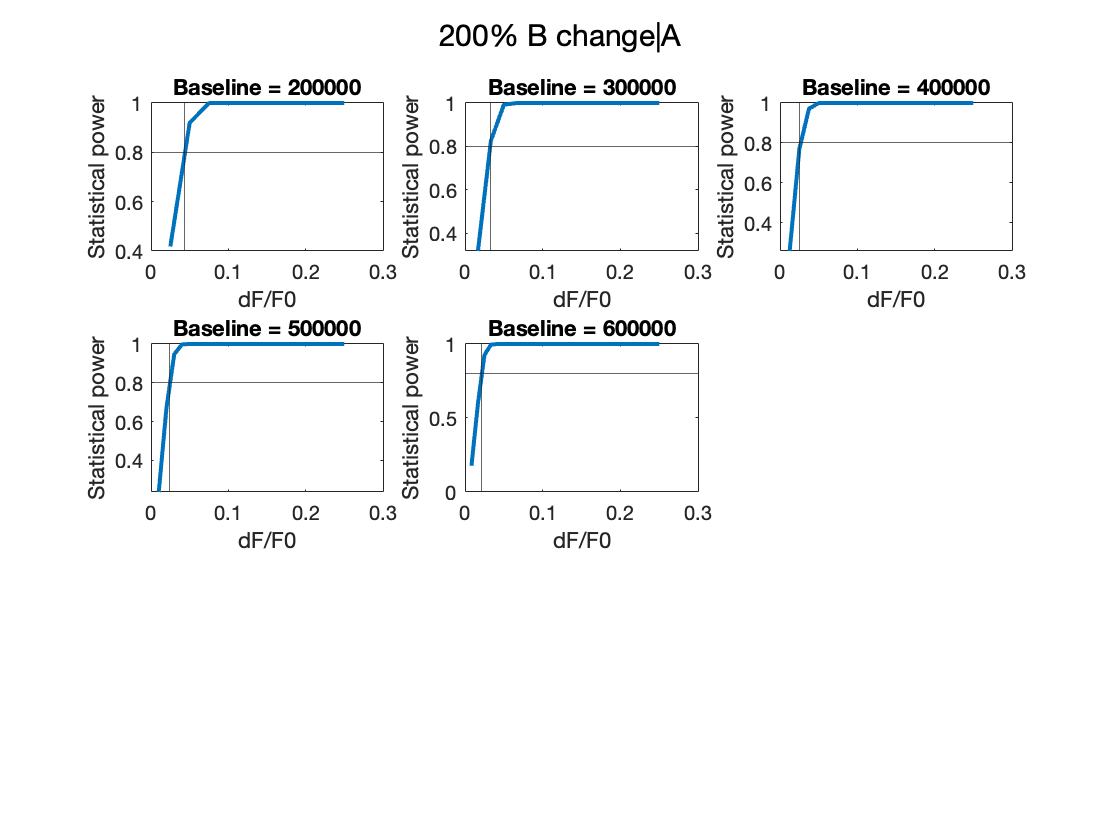

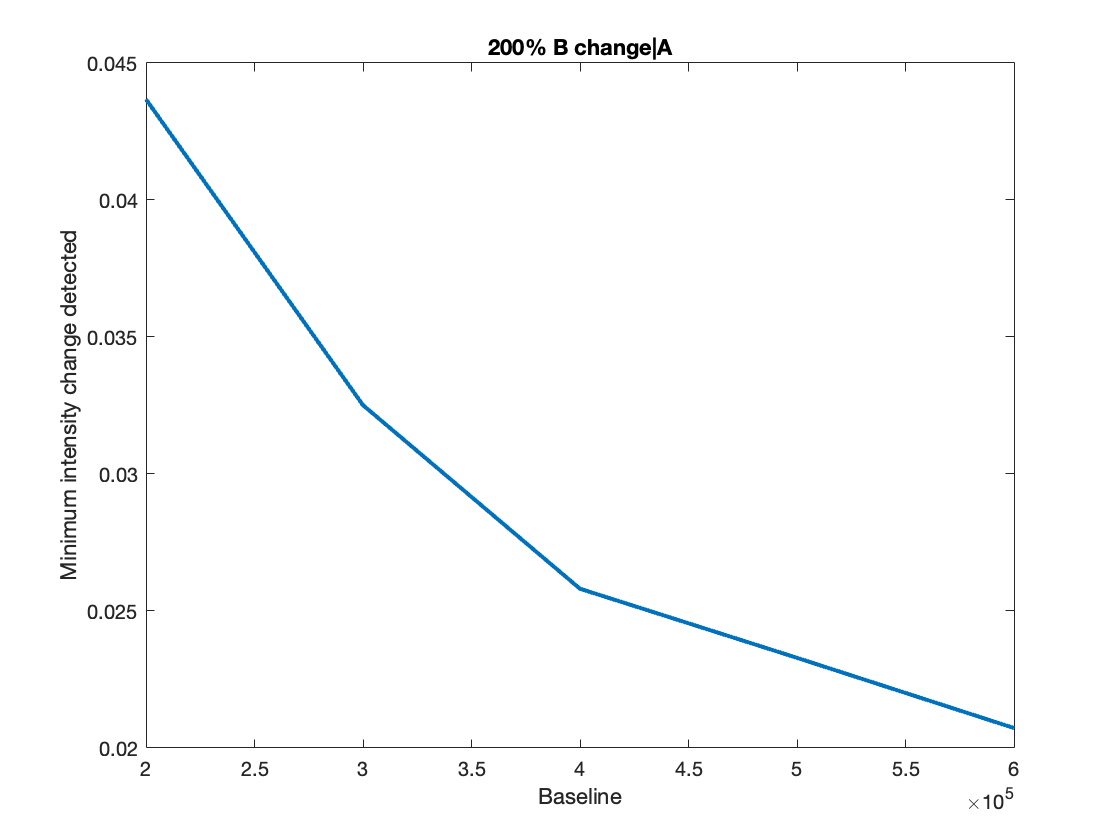

Minimum_detectable_change_A =     0.0437    0.0325    0.0258    0.0233    0.0207


[Minimum_detectable_change_A] = Calc_Minimum_Intensity_Change(SS_samples_A, intensity_change_step,Max_intensity_fold_change, beta_all_A, FigureTitle)

Minimum_detectable_change_A = Minimum_detectable_change_A*100;

% Calculating the minimal detectable difference of sensor B change
xsim = (0:1:511)*(50/256);
SaveName = {};
SaveName{1} = 'B_FittingResults_SS_start_';
SaveName{2} = '_20240503';
Beta_target = 'B';
tau1 = 2;
tau2 = 4;
[beta_all_B, A_intensity_all, A_intensity_raw_all, B_intensity_all, B_intensity_raw_all] = CalcIntensity_and_Beta(xsim, prf, SS_samples_B, SaveName, tau1, tau2, Beta_target);

intensity_change_step = 5000;
Max_intensity_fold_change = 0.25;
FigureTitle = '200% A change|B'

FigureTitle = '200% A change|B'

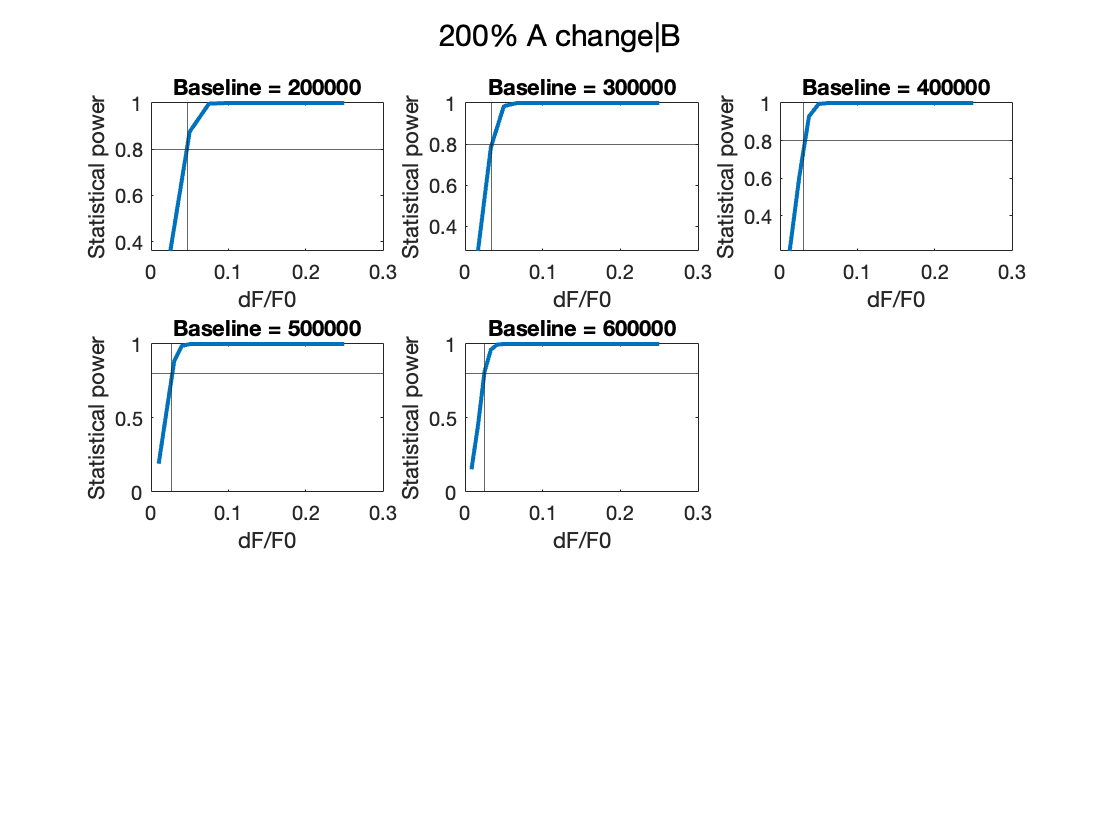

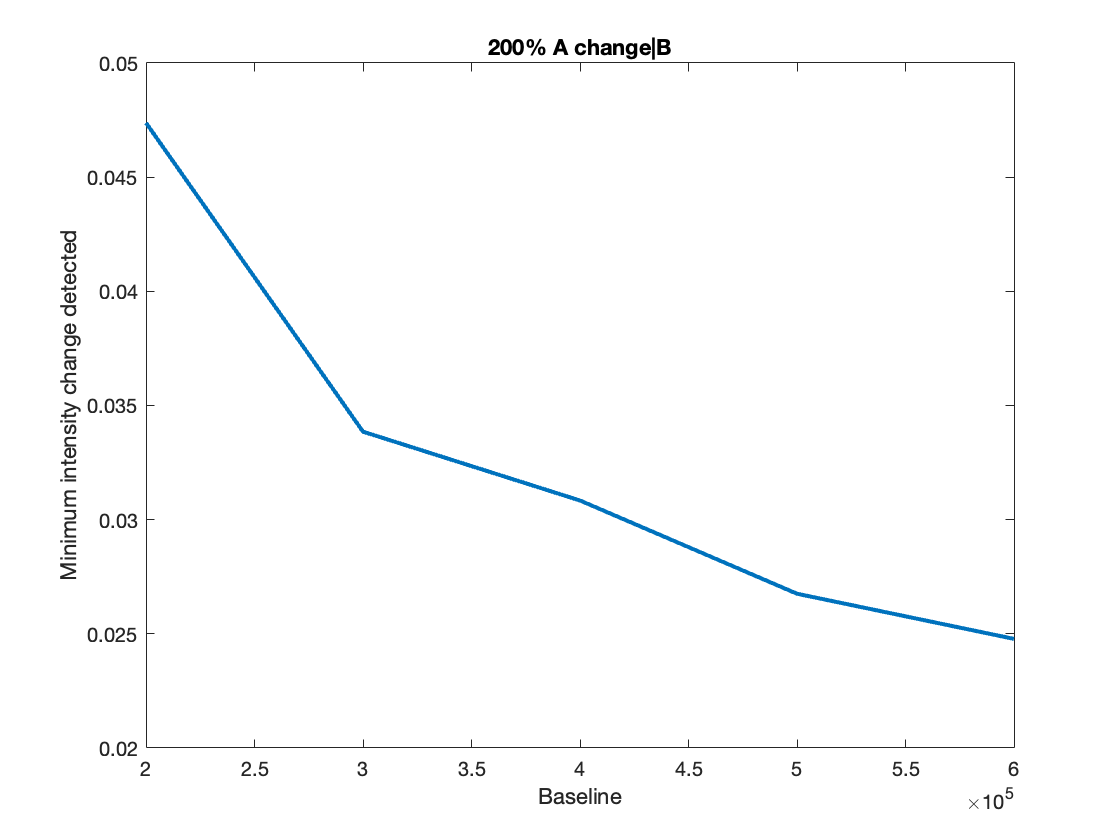

Minimum_detectable_change_B =     0.0474    0.0339    0.0308    0.0268    0.0248


[Minimum_detectable_change_B] = Calc_Minimum_Intensity_Change(SS_samples_B, intensity_change_step,Max_intensity_fold_change, beta_all_B, FigureTitle)

Minimum_detectable_change_B = Minimum_detectable_change_B*100;

function [p1_fitted, tau_empTrunc, fitting_parameters] = RunFitting(sample_num, n_all)

global spc
ch = 1;

pop1 = zeros(sample_num, 1);  % population 1
pop2 = zeros(sample_num, 1);  % population 2
p1_fitted = zeros(sample_num, 1);  % fitted p1
tau_avg = zeros(sample_num, 1); % lifetime calculated based on the fitting curve calculated to infinite
tau_avgTrunc = zeros(sample_num, 1); % lifetime calculated based on the fitting curve within fitting range
tau_empTrunc = zeros(sample_num, 1); % lifetime calculated empirically based on fitting range. This will be the average lifetime I use
chi2 = zeros(sample_num, 1); % chi square from fitting
beta6 = zeros(sample_num, 1); % SHG term from fitting
backcorr = zeros(sample_num, 1); % background term from fitting

fitting_parameters = {};

for k = 1:sample_num

    spc.lifetimes{1} = n_all{1}(k,:);

    if length(n_all) > 1

        for i_components = 2:length(n_all)

            spc.lifetimes{1} = spc.lifetimes{1} + n_all{i_components}(k,:);
        end

    end


    % initiate the fitting parameters
            
    spc.fits{1}.beta1 = 10000; % p1 and p2 as 0.5
    spc.fits{1}.beta3 = 10000;
    spc.fits{1}.beta5 = 0; % Delta peak time and SHG are fixed as 0
    spc.fits{1}.beta6 = 0;

    % Running the fitting
    spc_fitexp2prfGY(ch); 

    pop1(k,1) = spc.fits{ch}.beta1;
    pop2(k,1) = spc.fits{ch}.beta3;
    p1_fitted(k,1)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3); 
    tau_avg(k,1)=spc.fits{ch}.avgTau; 
    tau_avgTrunc(k,1)=spc.fits{ch}.avgTauTrunc;
    tau_empTrunc(k,1)=spc.fits{ch}.EmpTauTrunc;
    chi2(k,1)=spc.fits{ch}.redchisq;
    beta6(k,1)=spc.fits{ch}.beta6;
    backcorr(k,1)=spc.fits{ch}.backCorr;

end

fitting_parameters{1} = tau_avg;
fitting_parameters{2} = tau_avgTrunc;
fitting_parameters{3} = chi2;
fitting_parameters{4} = beta6;
fitting_parameters{5} = backcorr;
fitting_parameters{6} = pop1;
fitting_parameters{7} = pop2;

end


function y = Exp1Hist(xsim, tau, TP, prf)

ysim = TP*exp(-xsim/tau);

ysim_conv = conv(ysim, prf);
y = ysim_conv(1:256) + ysim_conv(257:512);

end





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [beta_all, A_intensity_all, A_intensity_raw_all, B_intensity_all, B_intensity_raw_all] = CalcIntensity_and_Beta(xsim,prf, SS_samples_A, SaveName, tau1, tau2, Beta_target)
        
        beta_all = {};
        A_intensity_all = {}; % Intensity information of fitted sensor A as cell variable; 1st row: intensity mean; 2nd rwo: intensity STD
        A_intensity_raw_all = {}; % Intensity of all the simulated samples

        B_intensity_raw = {}; % Intensity information of fitted sensor B as cell variable; 1st row: intensity mean; 2nd rwo: intensity STD
        B_intensity_raw_all = {}; % Intensity of all the simulated samples

        for i = 1:length(SS_samples_A)
        
            SS_A_start = SS_samples_A(i);
            x_intensity = transpose((5000:5000:SS_A_start)/SS_A_start);
            savename = [SaveName{1}, num2str(i), '_',  num2str(SS_A_start), SaveName{2}, '.mat'];
            SavedResults = load(savename);
        
            A_intensity_raw = {};
            A_intensity_mean = zeros(1, length(SavedResults.fitting_parameters));
            A_intensity_std = zeros(1, length(SavedResults.fitting_parameters));
        
            B_intensity_raw = {};
            B_intensity_mean = zeros(1, length(SavedResults.fitting_parameters));
            B_intensity_std = zeros(1, length(SavedResults.fitting_parameters));
        
            for j = 1:length(SavedResults.fitting_parameters)
        
                A_intensity = zeros(500, 1);
                B_intensity = zeros(500, 1);
        
                for k = 1:500
        
                    histogram_A_start = Exp1Hist(xsim, tau1, SavedResults.fitting_parameters{j}{6}(k), prf);
                    histogram_B_start = Exp1Hist(xsim, tau2, SavedResults.fitting_parameters{j}{7}(k), prf);
        
                    A_intensity(k) = sum(histogram_A_start);
                    B_intensity(k) = sum(histogram_B_start);
        
                end
        
                A_intensity_raw{1, j} = A_intensity;
                B_intensity_raw{1, j} = B_intensity;
        
                A_intensity_mean(1, j) = mean(A_intensity);
                A_intensity_std(1, j) = std(A_intensity);
        
                B_intensity_mean(1, j) = mean(B_intensity);
                B_intensity_std(1, j) = std(B_intensity);
        
        
            end

            A_intensity_all{1, i} = A_intensity_mean;
            A_intensity_all{2, i} = A_intensity_std;

            B_intensity_all{1, i} = B_intensity_mean;
            B_intensity_all{2, i} = B_intensity_std;

            A_intensity_raw_all{i} = A_intensity_raw;
            B_intensity_raw_all{i} = B_intensity_raw;
        
            betas = zeros(1, length(SavedResults.fitting_parameters)-1);
            for j = 1:length(SavedResults.fitting_parameters)-1
                if Beta_target == 'A'
                    dA_intensity = A_intensity_mean(1,j+1) - A_intensity_mean(1,1);
                    SEM = sqrt(A_intensity_std(1,j+1)^2 + A_intensity_std(1,1)^2);
            
                    betas(j) = 1-normcdf(1.96 - (dA_intensity/SEM));
                elseif Beta_target == 'B'
                    dB_intensity = B_intensity_mean(1,j+1) - B_intensity_mean(1,1);
                    SEM = sqrt(B_intensity_std(1,j+1)^2 + B_intensity_std(1,1)^2);
            
                    betas(j) = 1-normcdf(1.96 - (dB_intensity/SEM));
                end
        
            end
        
            beta_all{i} = betas;
        
        
        end

end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [Minimum_detectable_change] = Calc_Minimum_Intensity_Change(SS_samples_A, intensity_change_step,Max_intensity_fold_change, beta_all, FigureTitle)

        Minimum_detectable_change = zeros(1, length(SS_samples_A));
        
        figure
        
        for i = 1:length(SS_samples_A)
        
            SS_A_start = SS_samples_A(i);
            x_intensity = transpose((intensity_change_step:intensity_change_step:(SS_A_start*Max_intensity_fold_change))/SS_A_start);
        
            [cf, G] = L5P(x_intensity, transpose(beta_all{i}));
            A = cf.A;
            B = cf.B;
            C = cf.C;
            D = cf.D;
            E = cf.E; 
        
            syms x
            eqn = D + (A-D)/((1+(x/C)^B)^E) == 0.8;
            S = solve(eqn, x, 'Real', true);
        
            Minimum_detectable_change(i) = double(S);
        
            subplot(3,3,i)
            plot(x_intensity, beta_all{i}, 'LineWidth',2)
            title(['Baseline = ', num2str(SS_A_start)])
            xlabel('dF/F0')
            ylabel('Statistical power')
            xline(double(S))
            yline(0.8)
            sgtitle(FigureTitle)
        
        end
        
        
        figure
        plot(SS_samples_A, Minimum_detectable_change, 'LineWidth',2)
        xlabel('Baseline')
        ylabel('Minimum intensity change detected')
        title(FigureTitle)

end